# A Demo on Hyperspectral Linear Spectral Mixture Analysis with MATLAB

This demo notebook shows an example of Linear Spectral Mixture Analysis (LSMA) using MATLAB. We’ll cover: 1) Loading the hyperspectral data; 2) Estimating the number of endmembers using Noise-Whitened Harsanyi–Farrand–Chang (NWHFC); 3) Extracting endmembers using the Automatic Target Generation Process (ATGP); and 4) Performing linear unmixing using Non-negative Constrained Least Squares (NCLS) and Fully Constrained Least Squares (FCLS)

## 1. Download the Dataset from Github and Loading the Dataset

Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

load("tite/tite_reflectance.mat");
hsi=double(TI2);
M=double(minerals);

## 2. Visualization of TI2 Hyperspectral Imagery

The block sets up a tiled layout with two panels: one for visualizing  the 100th band of the hyperspectral image (hsi) using imagesc, and another for plotting spectral intensity across bands.

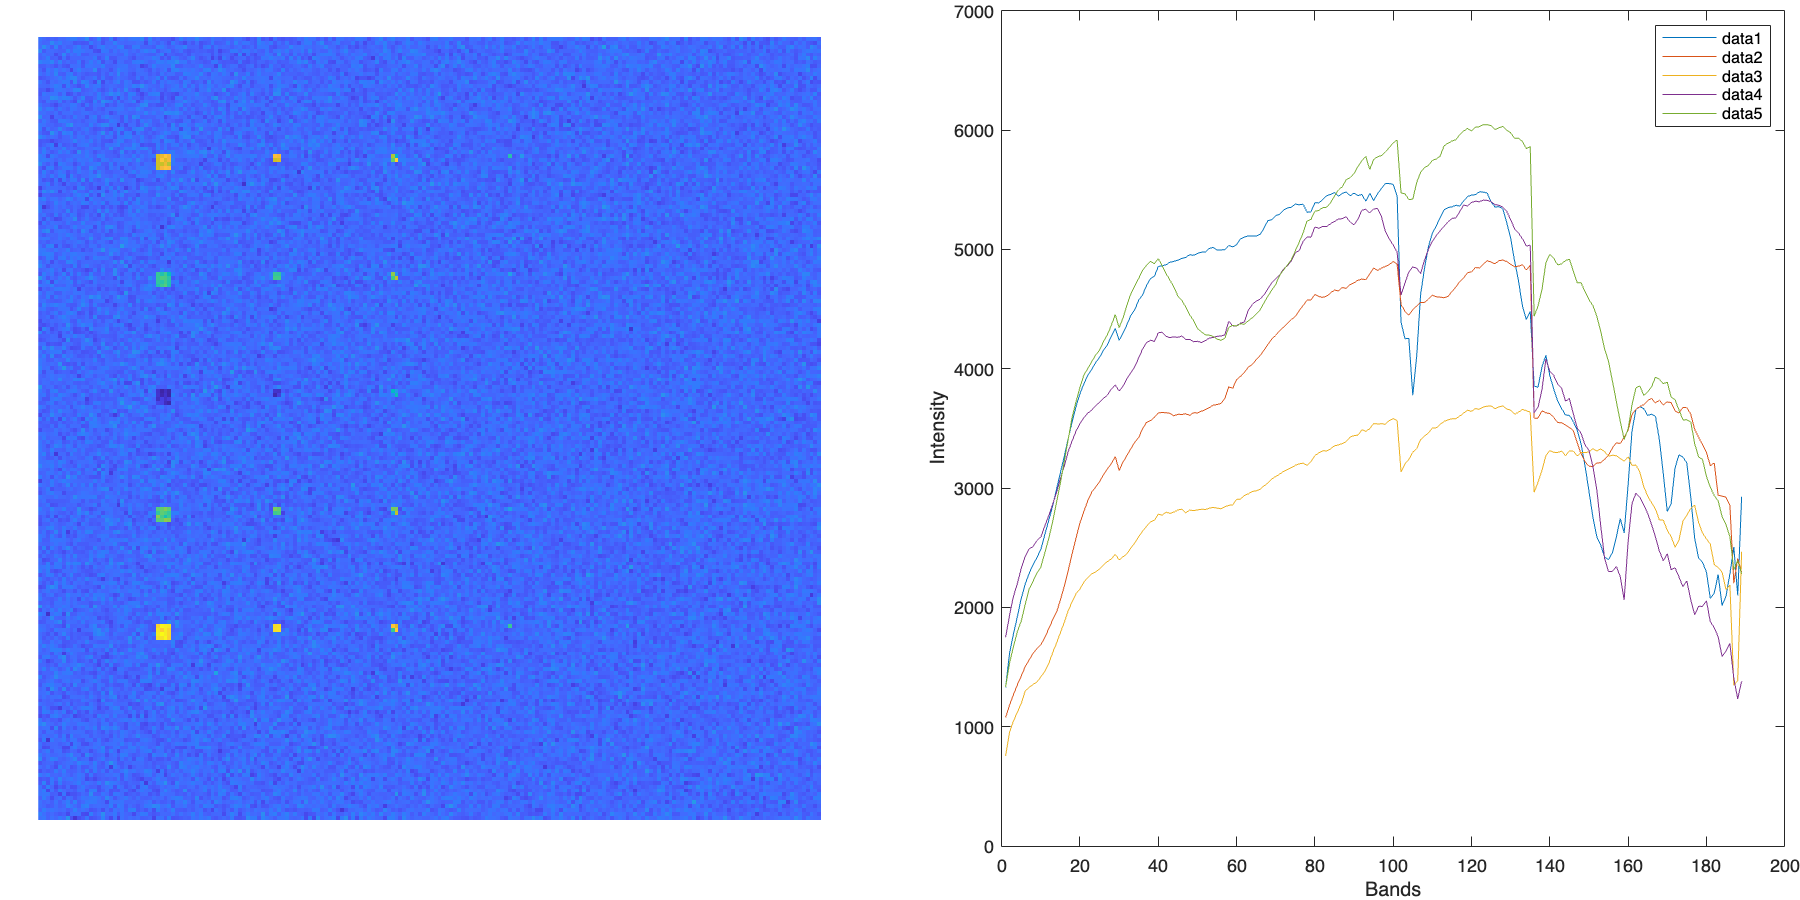

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

% First tile: Visualize the 100th band of the hyperspectral image
nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;

% Second tile: Plot the spectral intensity across bands
nexttile,plot(M);
legend;
xlabel("Bands");
ylabel("Intensity");

## 3. Estimate Number of Endmembers with Noise-Whitened Harsanyi–Farrand–Chang (NWHFC) 

Noise-Whitened Harsanyi–Farrand–Chang (NWHFC) is a method to estimate the number of endmembers in an HSI scene.

nVD=NWHFC(hsi,1e-4);
fprintf("This HSI scene contains %d endmembers.\n",nVD);

This HSI scene contains 5 endmembers.


## 4. Find Endmembers with Automatic Target Generation Process (ATGP)

The NWHFC estiamted nVD number is utilized as input to specific the number of endmember to be found by ATGP.

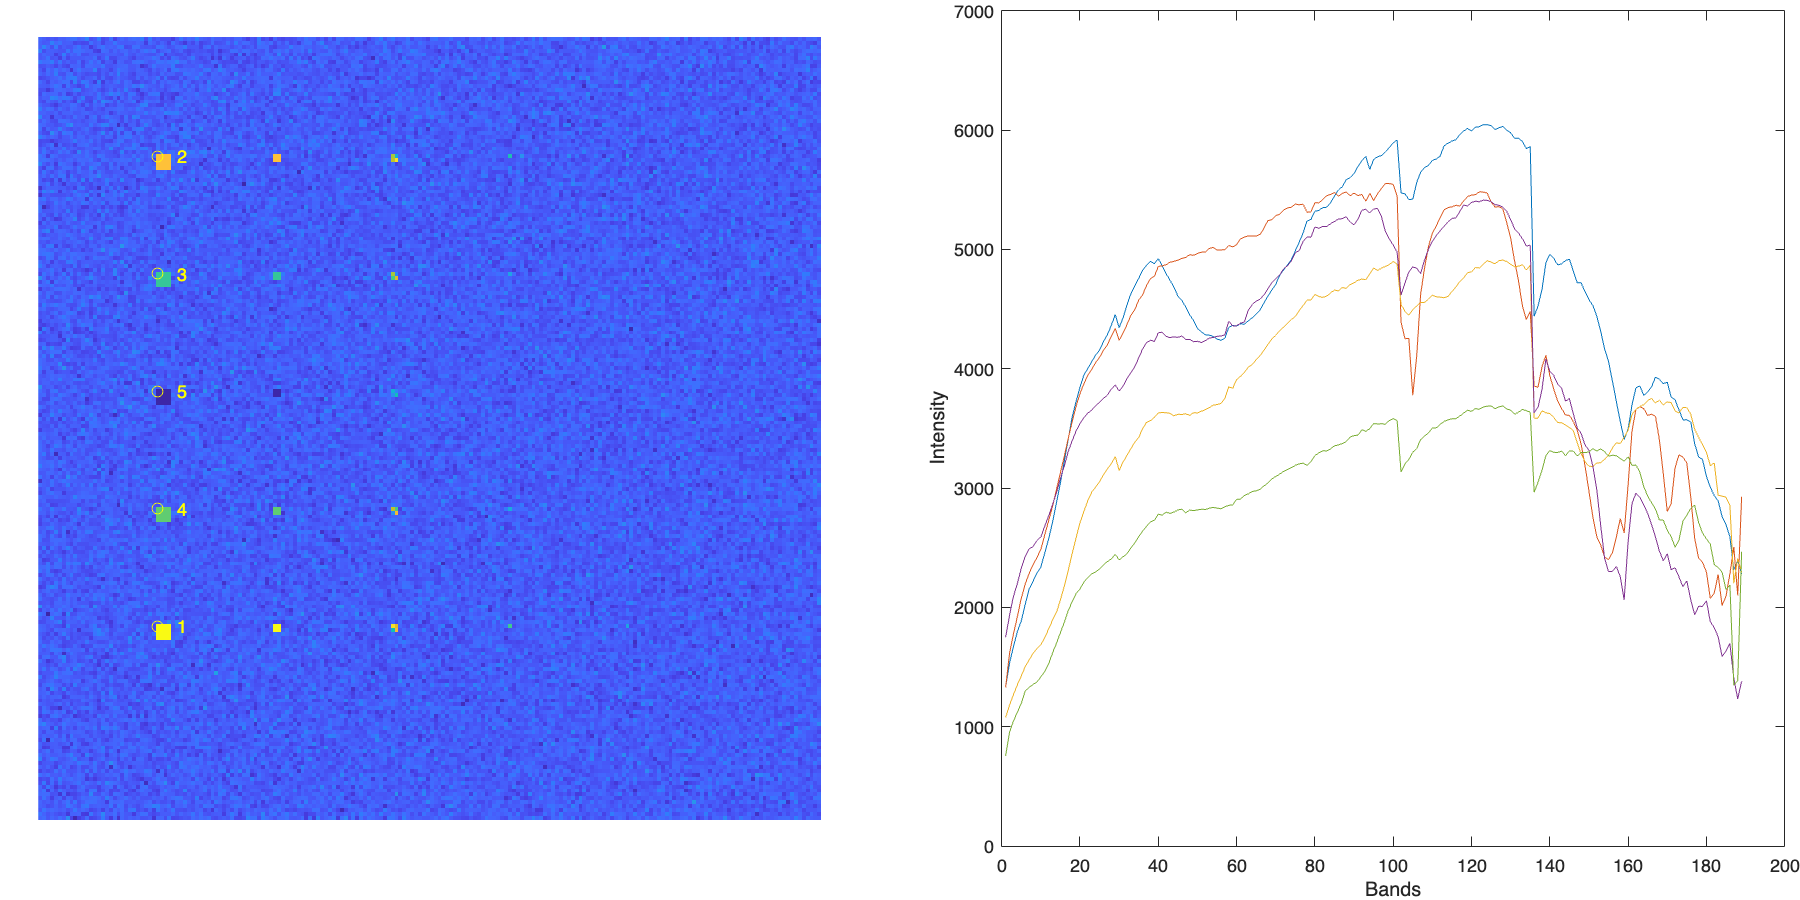

% ATGP
numTgt=nVD;
[posTgt,spTgt] = ATGP(hsi,numTgt);

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;
for idx = 1:numTgt
    hold on,plot(posTgt(idx,2),posTgt(idx,1),'yo');
    hold on,text(posTgt(idx,2)+5,posTgt(idx,1),num2str(idx),"Color","yellow");
end

nexttile;
plot(spTgt);
xlabel("Bands");
ylabel("Intensity");

## 5. Linear Unmixing using Non-negative Constrained Least Squares (NCLS)

Next, we use the NCLS method, with ATGP founded endmembers. Each subplot shows the abundance of endmember in the scene as computed by the NCLS method.

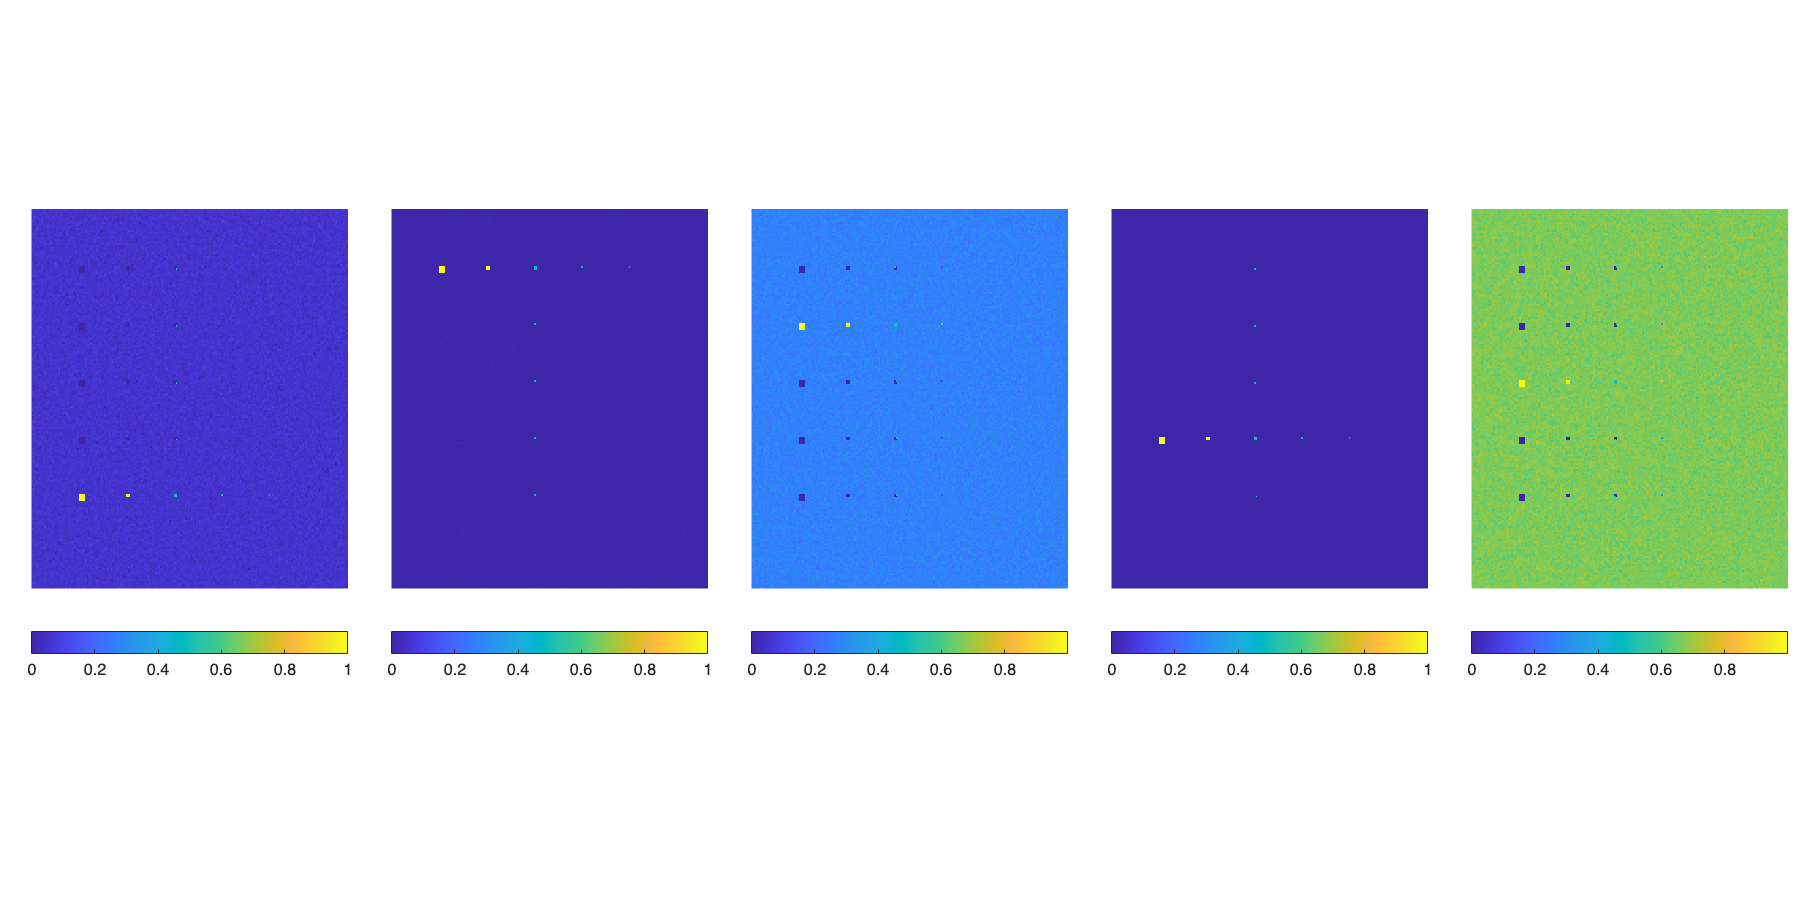

% NCLS
abundanceNCLS = NCLS(hsi, spTgt);
figure("Units","pixels","Position",[1,1,1200,500]);
tiledlayout(1,nVD,"TileSpacing","tight","Padding","tight");
for idx = 1:nVD
    nexttile,imagesc(abundanceNCLS(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## 6. Linear Unmixing using Fully Constrained Least Squares (FCLS)

Next, we use the FCLS method, with ATGP founded endmembers. FCLS adds both non-negativity and sum-to-one constraints to the unmixing problem. Each subplot represents the estimated abundance of a specific material, ensuring that the abundance follows non-negative and sum-to-one constraints.

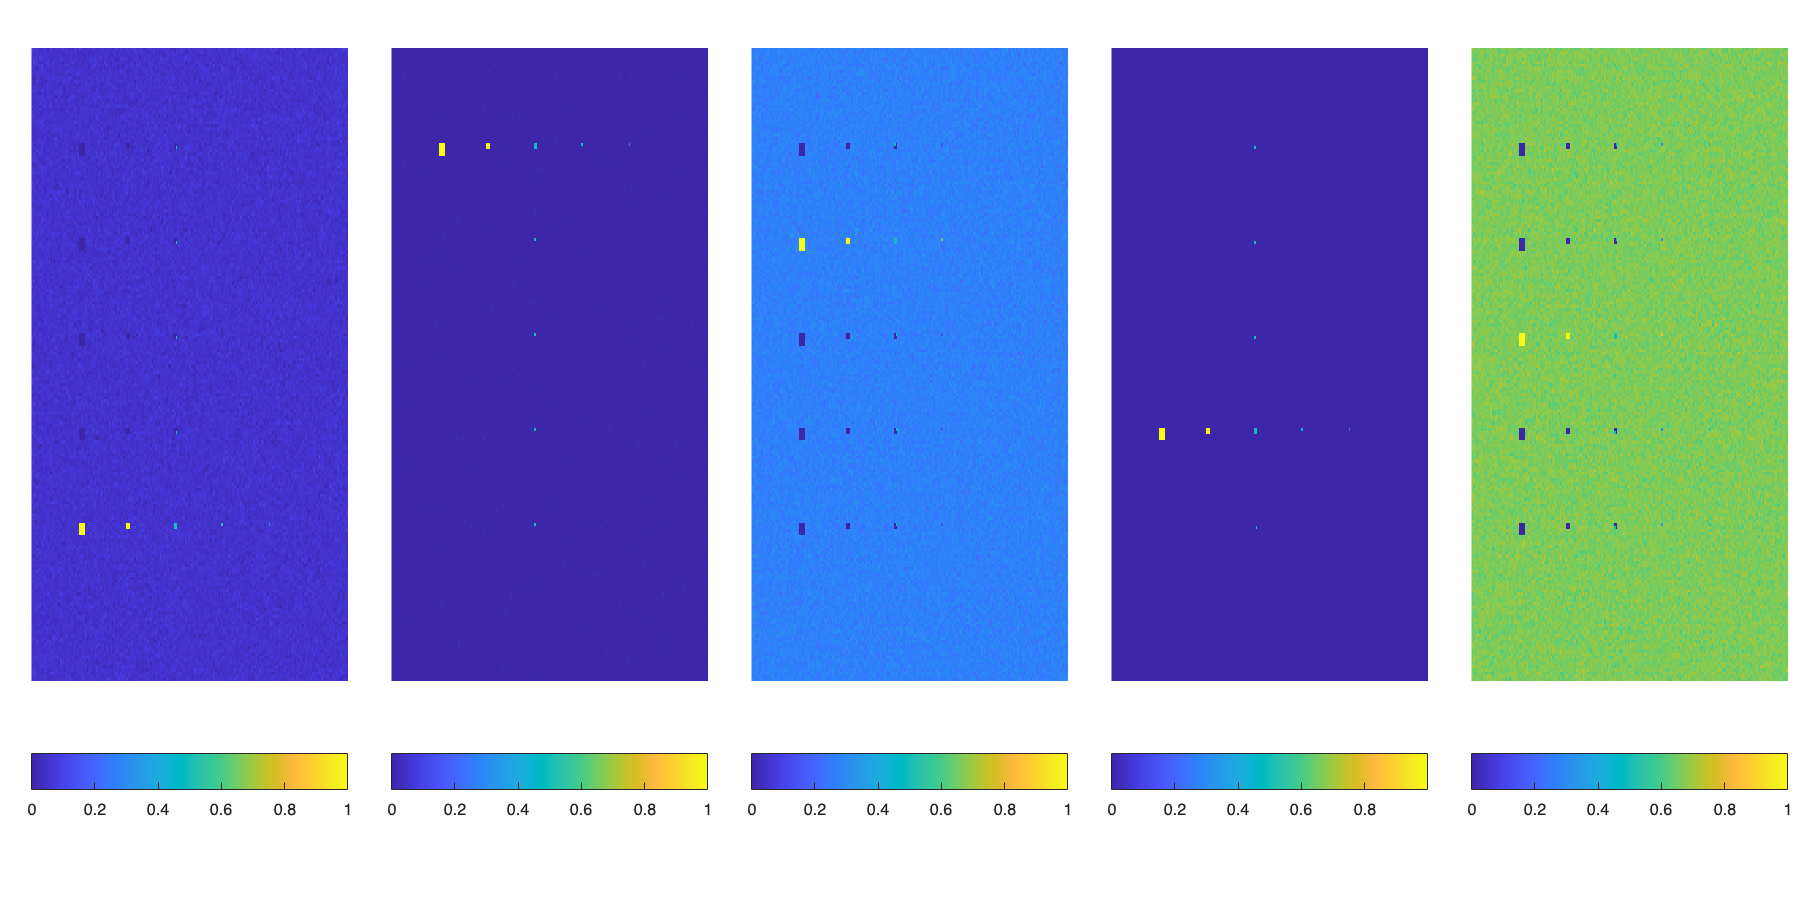

% FCLS
abundanceFCLS = FCLS(hsi, spTgt);
figure("Units","pixels","Position",[1,1,1200,300]);
tiledlayout(1,nVD,"TileSpacing","tight","Padding","tight");
for idx = 1:nVD
    nexttile,imagesc(abundanceFCLS(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

% Functions
% NWHFC
function nVD = NWHFC(HIM,P_fa)
    % Created by Wang, Jing
    % Modified by Xue, Bai
    [x,y,L] = size(HIM);
    N=x*y;
    r = reshape(HIM,N,L)';
    
    R = r*r'/N;
    u = mean(r,2);
    K = R-u*u';
    
    invK=inv(K); 
    tuta=diag(invK); 
    noiseK=1./tuta; 
    noiseK=diag(noiseK); 
    
    r_w=inv(sqrtm(noiseK))*r;

    R = r_w*r_w'/N;
    u = mean(r_w,2);
    K = R-u*u';

    D1=sort(eig(R),'descend');
    D2=sort(eig(K),'descend');

    sita=sqrt((D1.^2+D2.^2)*2/N);
    Threshold=(sqrt(2))*sita*erfinv(1-2*P_fa);

    valueVDEigen=0;
    for m=1:L
        if ((D1(m,1)-D2(m,1))>Threshold(m,1))
            valueVDEigen(m,1)=1;
        else 
            valueVDEigen(m,1)=0;
        end
    end
    nVD=sum(valueVDEigen);
end

% ATGP
function [posTgt,spTgt]=ATGP(HSI,p)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);

    [~,idxTgt] = max(sum(r.^2,2));
    spTgt=r(idxTgt,:)';
    
    for idx=2:p
        U=spTgt;
        P_U_Per=eye(L)-U*pinv(U'*U)*U';
        scoreATGP = sum((r*P_U_Per).^2,2);
        [~,idxNewTgt] = max(scoreATGP);
        idxTgt(end+1)=idxNewTgt(1);
        spTgt(:,end+1)=r(idxNewTgt(1),:)';
    end

    [posTgt(:,1),posTgt(:,2)] = ind2sub([x,y],idxTgt);

end

function abundanceNCLS = NCLS(HSI,M)
    [x,y,L] = size(HSI);
    p=size(M,2);

    N=x*y;
    r=reshape(HSI,N,L)';

    options = optimset('TolX',1e-4,"Display","off");

    abundanceNCLS = zeros(N,p);
    for idx = 1:N
        abundanceNCLS(idx,:) = lsqnonneg(M,r(:,idx),options);
    end
    abundanceNCLS = reshape(abundanceNCLS,x,y,p);
end

function abundanceFCLS = FCLS(HSI,M)
    [x,y,L] = size(HSI);
    p=size(M,2);

    N=x*y;
    r=reshape(HSI,N,L)';

    M=[M;ones(1,p)];
    r=[r;ones(1,N)];

    options = optimset('TolX',1e-4,"Display","off");

    abundanceFCLS = zeros(N,p);
    for idx = 1:N
        abundanceFCLS(idx,:) = lsqnonneg(M,r(:,idx),options);
    end
    abundanceFCLS = reshape(abundanceFCLS,x,y,p);
end